# Visualize Vector Fields Using Stream Ribbons

`streamribbon` draws 3D ribbon streamlines from provided vector volume data. The shape of the ribbon is determined by the curl of the provided data as well as user defined width.

## Load Wind Vector Field

Load the built in wind vector field and set a volume of points for the stream ribbon to be evaluated at.

load wind
[sx,sy,sz] = meshgrid(80,20:10:50,0:5:15);

## Basic Streamribbon Plot

Use the `streamribbon` function to indicate flow in the wind data set. The inputs include the coordinates, vector field components, and starting location for the stream ribbons. 

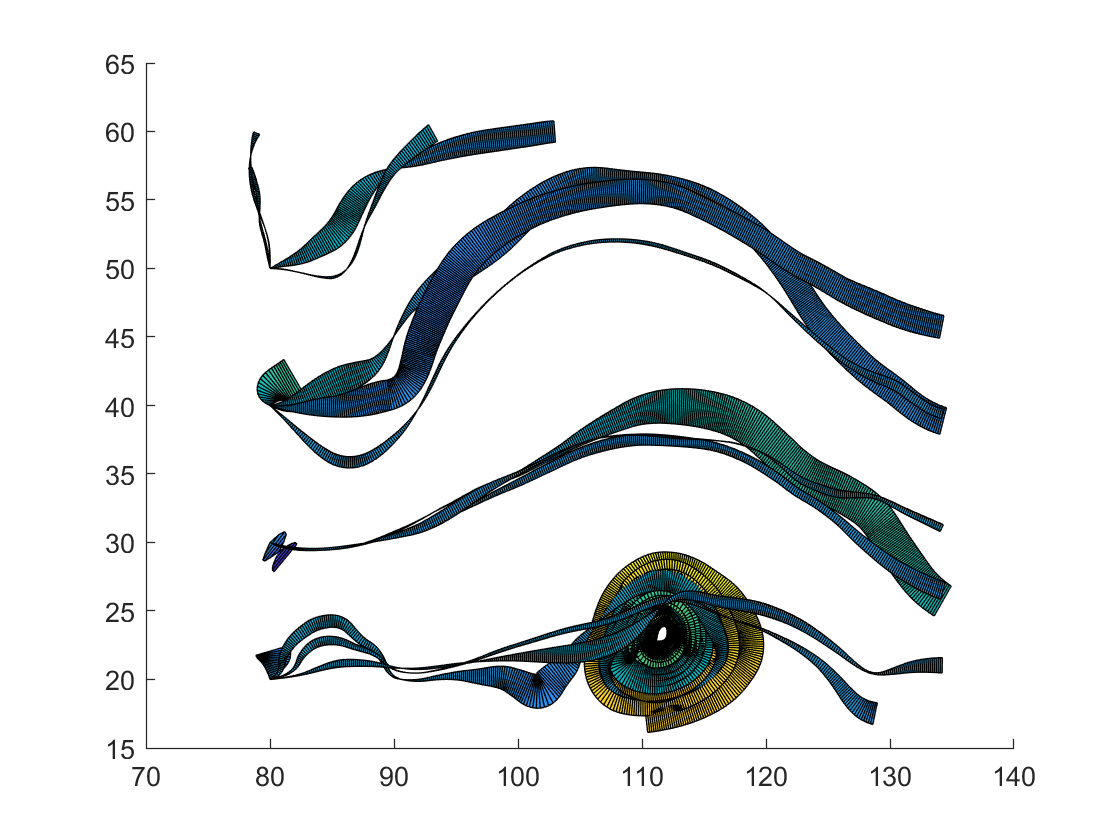

streamribbon(x,y,z,u,v,w,sx,sy,sz);

## Customizations

### Specify Viewing Options

Viewing parameters for the plot can be adjusted to improve readability. An isometric view can be positioned programmatically through the `view` command. Shading and lighting parameters can also be manipulated to provide optimal visibility. A light source is specified to the right with gouraud lighting options and interpolated shading.

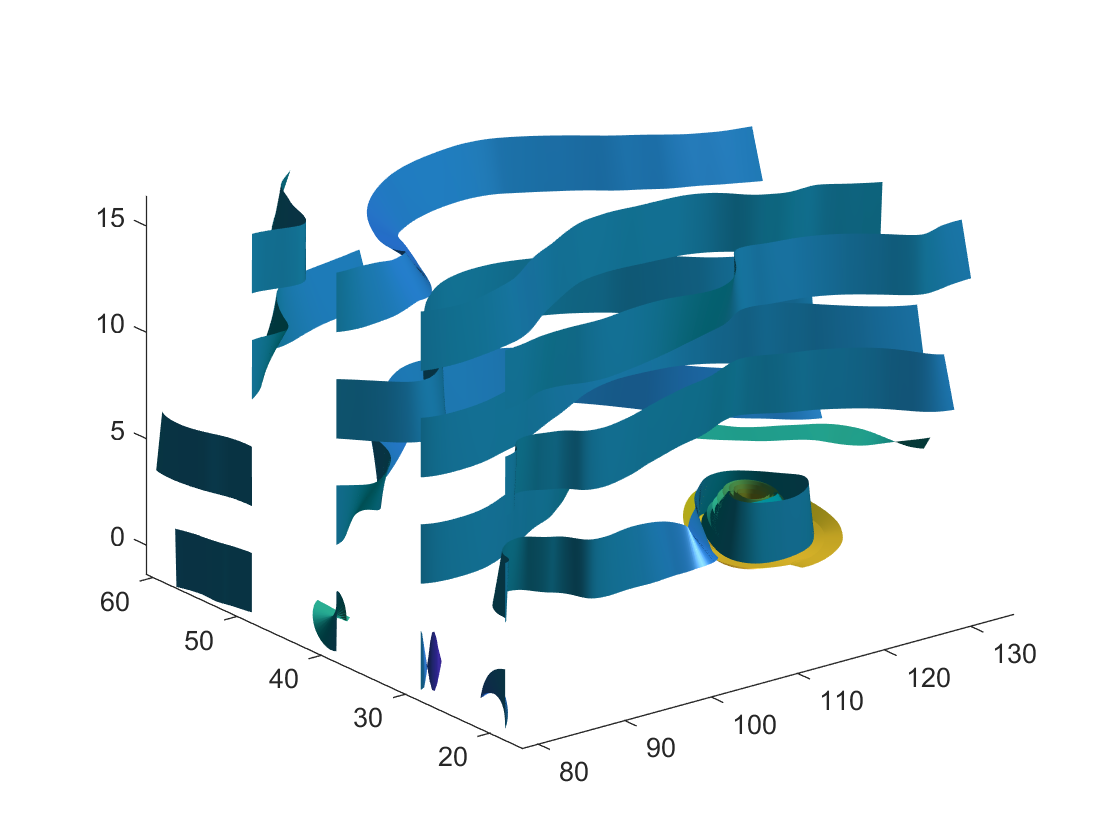

view(3)                                     % set isometric view
axis tight                                  % fit the axes
shading interp                              % specify the shading options
camlight right                              % specify light source location
lighting gouraud                            % set lighting algorithm

### Specify Twist Angles 

For the time based vector field defined as $\left\langle \cos \left(t\right),\;\;\sin \left(t\right),\;\;\frac{t}{3}\right\rangle$, an angle twist over time can be defined using a trigonometric function where the angle = $\cos \left(t\right)$. 

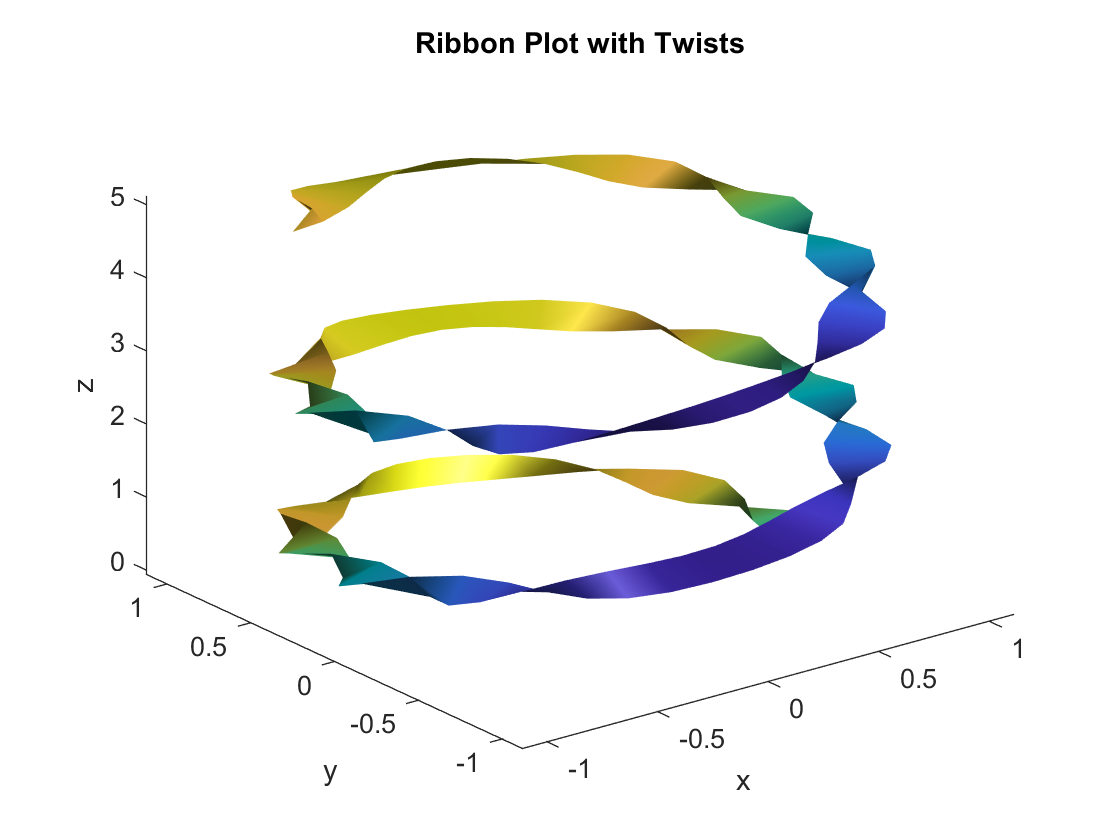

% Define 3-D function
t = 0:.15:15;
verts = {[cos(t)' sin(t)' (t/3)']};

% define the twist function
twistangle = {cos(t)'};

% plot the stream ribbon
figure
sr = streamribbon(verts,twistangle);
axis tight                                  % fit the axes
shading interp                              % specify the shading options
view(3)                                     % set isometric view
camlight 
lighting gouraud                            % set lighting algorithm

title('Ribbon Plot with Twists')
xlabel('x')
ylabel('y')
zlabel('z')

## Additional Information

### Get All Streamribbon Properties

Graphics objects in MATLAB have many properties. To see all the properties of a streamribbon, uncomment the following code

% get(sr)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[streamribbon](https://www.mathworks.com/help/matlab/ref/streamribbon.html)